# パラメータを更新

clear

% 効率
eta = 0.7; % 走行抵抗やギアの損失をもろもろ考慮した効率

% 機構的なパラメータ
m = 120e-3; % 重量[kg]
T = 100e-3; % トレッド[m]
r = 11e-3; % タイヤの半径[m]

% モータのパラメータ
V_input = 12.6; % 印加電圧[V]
V_nominal = 4.5; %モータの公称電圧[V]
voltage_constant_times = V_input / V_nominal;

n_max = 12000 * voltage_constant_times; % 無負荷回転数[rpm]
omega_max = (n_max * 2 * pi) / 60; % 無負荷角速度[rad/s]
T_max = 5.45e-3 * voltage_constant_times; % 停動トルク[Nm]

n_const = 2710 * voltage_constant_times; % 回転数定数[rpm/V]
omega_const = n_const * 2 * pi / 60; % 角速度定数[rad/V]
T_const = 3.52e-3 * voltage_constant_times; %トルク定数[Nm/A]


% 要求パラメータ
max_velocity = 5; % 最高速度[m/s]
max_acceleration = 25; % 最高加速度[m/s^2]

# 台形加速をプロット

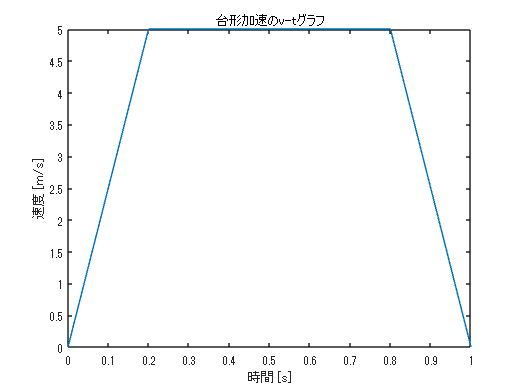

delta_t = 0.001; % シミュレーションのステップ時間
simulation_time = 1; % シミュレーションの時間[s]

t = 0 : delta_t : simulation_time; % 時間
velocity = zeros(1, length(t));
v0 = 0;
velocity(1) = v0; % 初速 [m/s]

acc_time = (max_velocity - v0) / max_acceleration; % 加速&減速にかかる時間[s]
const_time = simulation_time - 2 * acc_time; %等速で動く時間[s]

% シミュレーション
time = 0;
for i = 2 : length(t)
    if 0 <= time && time <= acc_time % 加速時間
        velocity(i) = velocity(i-1) + max_acceleration * delta_t;
        if(velocity(i) >= max_velocity) 
            velocity(i) = max_velocity;
        end
    elseif acc_time < time && time <= (acc_time + const_time) % 等速時間
        velocity(i) = max_velocity;
    elseif (acc_time + const_time) < time && time <= simulation_time % 減速時間
        velocity(i) = velocity(i-1) - max_acceleration * delta_t;
    end
    
    time = time + delta_t;
end

velocity(end) = v0;

% プロット
t = 0 : delta_t : simulation_time;
plot(t, velocity);
xlabel('時間 [s]')
ylabel('速度 [m/s]')
% ylim([0 5.3])
title('台形加速のv-tグラフ')

# モータの特性をプロット

#### 回転数-トルク特性

% sloop = -n_max / T_max; %傾きを計算
% fplot(@(x) sloop * x + n_max, [0 T_max]);
torque_motor = linspace(0, T_max);
n_motor = linspace(n_max, 0);
plot(torque_motor, n_motor);
xlabel("トルク [Nm]")
ylabel("回転数 [rpm]")

#### 出力特性

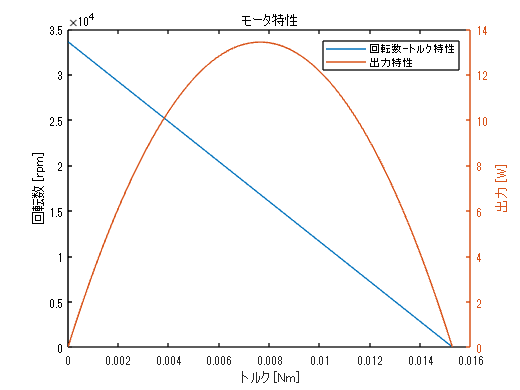

omega_motor = linspace(omega_max, 0);
P_motor = torque_motor .* omega_motor; %出力を計算

hold on
yyaxis right
plot(torque_motor, P_motor);
ylabel("出力 [W]")
legend("回転数-トルク特性", "出力特性")
title("モータ特性")

cla reset
hold off

P_motor = max(double(P_motor)) %モータの最大出力

P_motor = 13.4220

p_motor = (omega_max / 2) * (T_max / 2) % 厳密解

p_motor = 13.4234

# タイヤに必要な出力を算出

対向2輪ロボットで，各車輪は1つのモータで駆動していると仮定します．

% タイヤに必要な角速度とトルク．走行抵抗などで余計にトルクが必要な場合を効率として考慮
omega_tire_need = (max_velocity / r);
torque_tire_need = (r * (m/2) * max_acceleration) / eta; % タイヤが2個ついているので1つのタイヤにかかる重量は半分

% タイヤに必要な出力（効率考慮済み）
P_tire_need = omega_tire_need * torque_tire_need

P_tire_need = 10.7143

# 条件を満たす減速比の範囲を計算

syms omega_m gamma T_m T_n omega_n
eqn = omega_m * gamma == (omega_m/T_m) * gamma^2 * T_n + omega_n 

$$eqn = \gamma \,\omega_{m}=\omega_{n}+\frac{T_{n}\,\gamma^{2}\,\omega_{m}}{T_{m}}$$


eqn_gamma = solve(eqn, gamma) %減速比について解く（減速比：γ）

$$eqn\_gamma = \left(\begin{array}{c} \frac{T_{m}\,\left(\omega_{m}+\sqrt{\frac{\omega_{m}\,\left(T_{m}\,\omega_{m}-4\,T_{n}\,\omega_{n}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}}\\ \frac{T_{m}\,\left(\omega_{m}-\sqrt{\frac{\omega_{m}\,\left(T_{m}\,\omega_{m}-4\,T_{n}\,\omega_{n}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}} \end{array}\right)$$


eqn_gamma_num = subs(eqn_gamma, [omega_m T_m T_n omega_n], [omega_max T_max torque_tire_need omega_tire_need]) % 値を代入

$$eqn\_gamma\_num = \left(\begin{array}{c} \frac{763\,\left(1120\,\pi +\sqrt{\frac{8000000\,\pi \,\left(\frac{10682\,\pi }{625}-\frac{300}{7}\right)}{109}}\right)}{2640000\,\pi }\\ \frac{763\,\left(1120\,\pi -\sqrt{\frac{8000000\,\pi \,\left(\frac{10682\,\pi }{625}-\frac{300}{7}\right)}{109}}\right)}{2640000\,\pi } \end{array}\right)$$


g = double(eqn_gamma_num)

g =     0.4691
    0.1783


# プロットしてみる

#### 減速比が低いとき（速度重視）

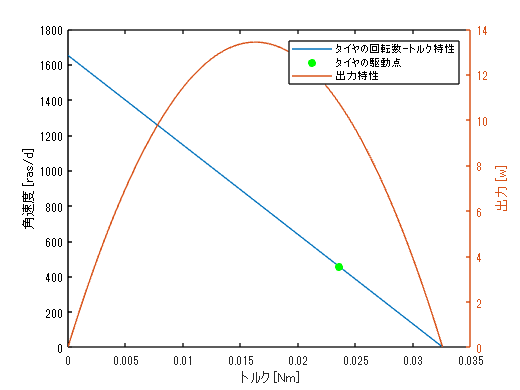

%減速比をかけた角速度-トルク曲線をプロット
ratio_min = g(1);
torque_motor_ratio_min = linspace(0, T_max * (1/ratio_min));
omega_motor_ratio_min= linspace(omega_max * ratio_min, 0);

plot(torque_motor_ratio_min, omega_motor_ratio_min); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

% 出力をプロット
P_ratio_num = torque_motor_ratio_min .* omega_motor_ratio_min; %出力を計算
yyaxis right
hold on
plot(torque_motor_ratio_min, P_ratio_num); % 出力特性
ylabel("出力 [w]")

% 加減速時の駆動点をプロット
yyaxis left
scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
hold off

legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性")


cla reset

#### 減速比が高いとき（加速重視）

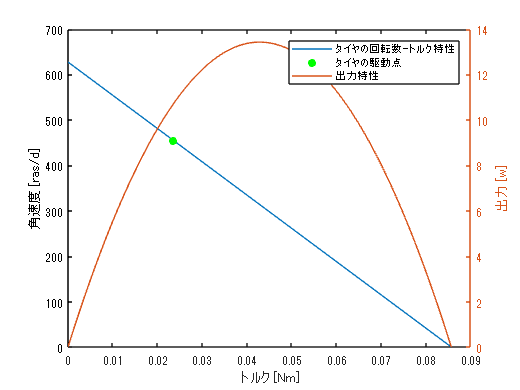

%減速比をかけた角速度-トルク曲線をプロット

ratio_max = g(2);
torque_motor_ratio_max = linspace(0, T_max * (1/ratio_max));
omega_motor_ratio_max = linspace(omega_max * ratio_max, 0);

plot(torque_motor_ratio_max, omega_motor_ratio_max); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

% 出力をプロット
P_ratio_num = torque_motor_ratio_max .* omega_motor_ratio_max; %出力を計算
yyaxis right
hold on
plot(torque_motor_ratio_max, P_ratio_num); % 出力特性
ylabel("出力 [w]")

% 加減速時の駆動点をプロット
yyaxis left
scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
hold off

legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性")


cla reset

#### 重ねて表示

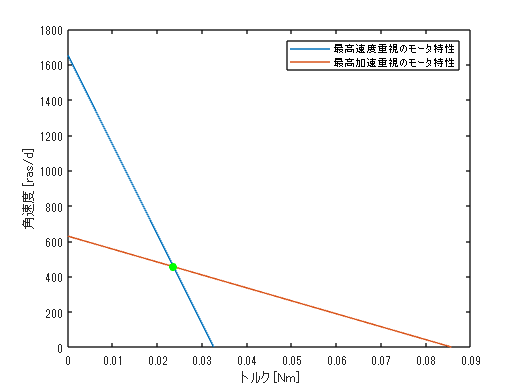

plot(torque_motor_ratio_min, omega_motor_ratio_min, torque_motor_ratio_max, omega_motor_ratio_max); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

hold on
% 加減速時の駆動点をプロット
scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
hold off

legend("最高速度重視のモータ特性", "最高加速重視のモータ特性")